## Frequency domain Analysis

figure
hold

Current plot held


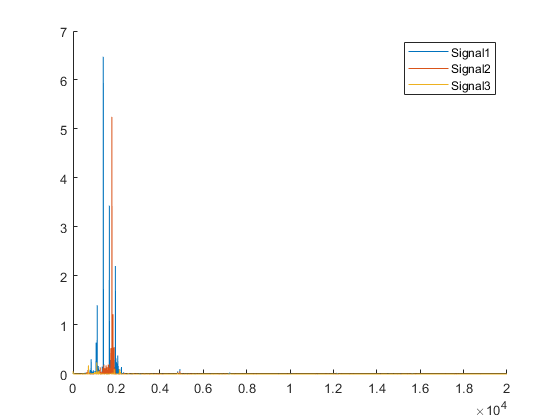

for ii = 1:length(x)
    [s,f] = pwelch(rawdata{ii},window(@rectwin,length(rawdata{ii})),[],length(rawdata{ii}),data.fs);
    plot(f,s,'Displayname',['Signal' num2str(ii)]')
end
legend toggle
hold off

### Getting Seperate Graphs

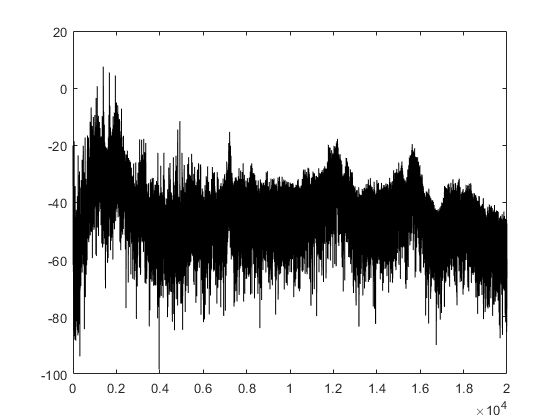

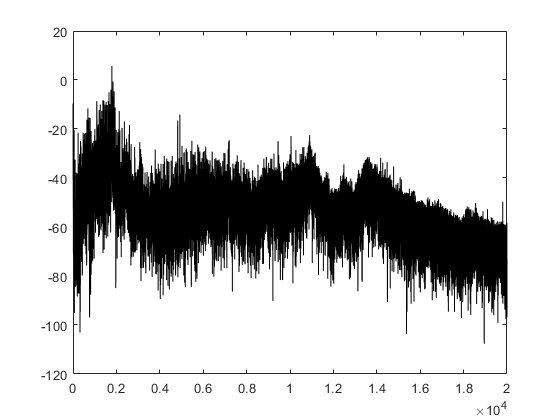

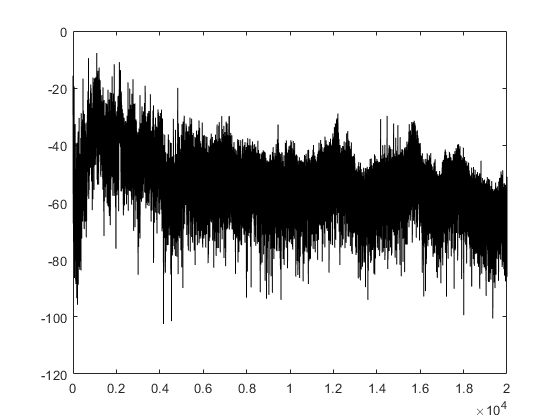

for ii = 1:length(x)
    [s,f] = pwelch(rawdata{ii},window(@hann,length(rawdata{ii})),[],length(rawdata{ii}),data.fs);
    figure
    plot(f,10*log10(s),'k')
end

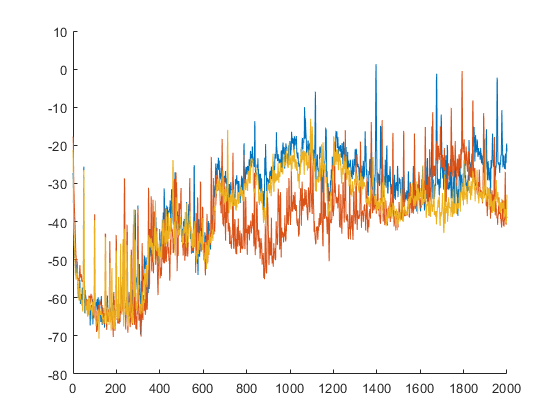


nfft = 2^15;
noverlap = nfft/2;
figure
hold on
for ii = 1:length(x)
    [s,f] = pwelch(rawdata{ii},window(@hann,nfft),noverlap,nfft,data.fs);
    plot(f,10*log10(s))
end
hold off
xlim([0 2000])

ylim([-70,5])


## Finding the Type of Damage

### Data

nwk = 14;
Dw = 3.7; % Rolling Element Dia in mm
Dt = 26.15; % Part Cirlce Dia in mm
alpha = 0; % Contact Angle in degrees

fko = 0.5 * fre * (1-(Dw/Dt)*cos(alpha));

fki = 0.5 * fre * (1+(Dw/Dt)*cos(alpha));

fa = 0.5 * fre * nwk * (1-(Dw/Dt)*cos(alpha));

fi = 0.5 * fre * nwk * (1+(Dw/Dt)*cos(alpha));

fwa = 0.5 * fre * (Dt/Dw) * (1-((Dw/Dt)*cos(alpha))^2);

fw = 2 * fwa;

damaged_fre = [fko;fki ;fa ;fi ;fwa ;fw]

hold on


spacing = (1 : ((20000/fko(1,1)))) * fko(1,1);
% spacing = damaged_fre(1,1) .* (1:1:damaged_fre(1,1))

% repmat(spacing,3,1)
plot(repmat(spacing,2,1),ylim,'--k','LineWidth',1)

hold off
